# Generating Sounds over Matlab

## I - Creating Sinus Pulse

clear                                  % Clear all data stored in variables
Amplitude = 0.1;                         % 1V     
samplingFrequency = 48000;             % 48 KHz
frequency = 20e+3;                     % 20 KHz
duration = (95999/samplingFrequency);    % ~ 21.3 ms 
t = 0:1/samplingFrequency:duration;    % Time Vector

sinusPulse = Amplitude*sin(2*pi*frequency*t); % sinusPulse(t) = 1*sin(2*pi*1000*t)

### I- 1- Plotting Sinus

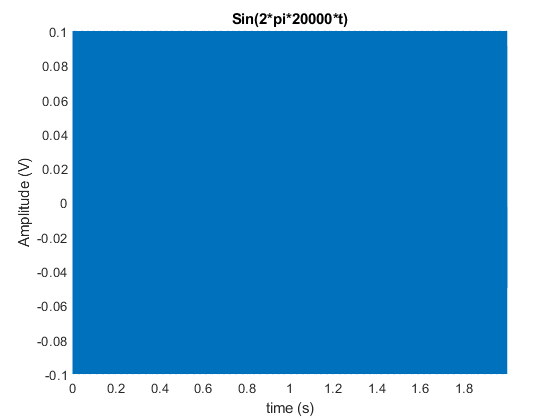

plot(t,sinusPulse); 
title('Sin(2*pi*20000*t)')   % title
ylabel('Amplitude (V)')
xlabel('time (s)')
% ylim([-.7 .7])
xlim([0 max(t)])

### I- 3- Listening to the tone

sound(sinusPulse)  